# Motion estimation and compensation

## PART I. Video player

First we build a simple video player in Matlab, such that we can visulize the motion content of the video. 

clear variables; close all;
sequence = "bus"

sequence = "bus"

 
fileName = sprintf('%s_cif.y', sequence);
nFrames = dir(fileName).bytes/288/352;
frameRate = 30;
frameTime = 1/frameRate;
fprintf('\nLoading the video file %s\n',fileName);


Loading the video file bus_cif.y


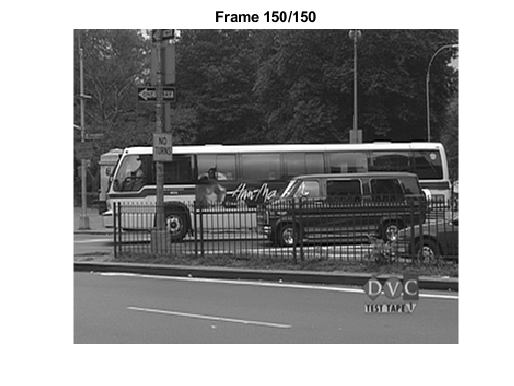

for k=1:nFrames,
    time = clock;
    current = readFrame(fileName, k-1 );
    figure(1); image(uint8(current)); axis image; axis off
    colormap(gray(256)); axis image; title(sprintf('Frame %3d/%3d',k, nFrames));
    elapsedTime = etime(clock,time);
    if elapsedTime < frameTime,
        pause(frameTime-elapsedTime);
    end
end

## PART II. Motion Estimation

Now we perform the block-based motion estimation. Let us start by selecting the ME parameters

% Index of "current" image
k = 48;
% Index of "reference" image
deltaT = 6;
h=k+deltaT; 
log2blockSize = 3;
blockSize = 2^log2blockSize;
searchRadius = 22;

verbose = true;

regularization= false;
log10lambda = -1;
lambda = 10^log10lambda;
 
if verbose,
    fprintf('\nMotion estimation\nBlock size:\t%2dx%2d\nSearch radius:\t%2d\nCurr Image:\t%3d\nRef Image:\t%3d\n\n', ...
        blockSize,blockSize,searchRadius,k,h);
    if regularization
        fprintf('Regularized ME with lambda: %6.3f\n',lambda);
    else
        fprintf('Non-regularized ME\n');
    end
end


Motion estimation
Block size:	 8x 8
Search radius:	22
Curr Image:	 48
Ref Image:	 54



Non-regularized ME


Read the two images from the gray-scale video file

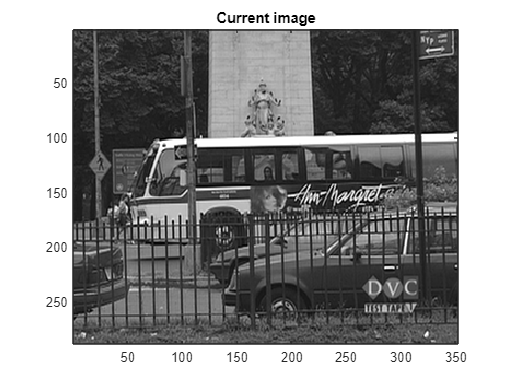

current = readFrame(fileName, k-1 );
reference = readFrame(fileName, h-1 );

figure(2); image(uint8(current));
colormap(gray(256)); axis image; title('Current image');

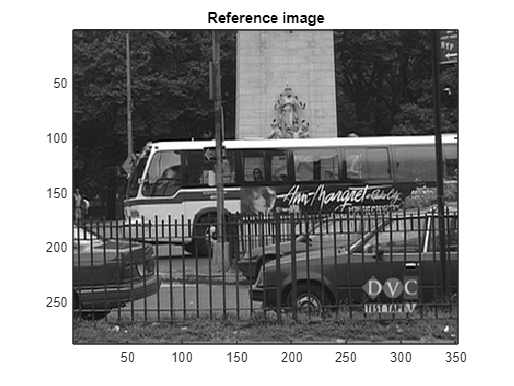

figure(3); image(uint8(reference));
colormap(gray(256)); axis image; title('Reference image');

Compute the estimated motion vector field between the two images

tStart = tic; % Start the timer
if regularization
    MVF = meReg(current,reference,blockSize,blockSize,searchRadius,lambda);
else
    MVF = me(current,reference,blockSize,blockSize,searchRadius);
end
tEnd = toc(tStart);  % Stops the timer 
fprintf('Elapsed time %5.3f ms\n', tEnd*1e3)

Elapsed time 4393.647 ms


Show the MVF using displayMVF

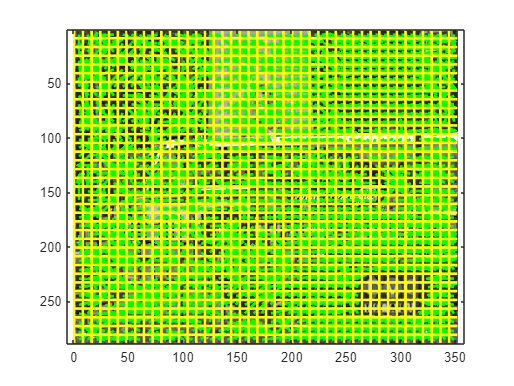

figure(4);

displayMVF(current,MVF,blockSize,blockSize);

Use the `mc` function to implement motion compensation

compensated = mc(reference,MVF);

Use the codingCost function to compute the coding cost of the MVF, estimated as the entropy of the vector components

bitCost = codingCost(MVF,blockSize);
if verbose,
    fprintf('Coding cost: %d bits\n%5.2f bits/vector\n%5.3f bits per pixel\n',bitCost,bitCost/(numel(MVF)/2/blockSize/blockSize), bitCost/numel(current) );
end

Coding cost: 15521 bits
 9.80 bits/vector
0.153 bits per pixel


Compute the PSNR between the current image and its prediction obtained as motion compensation of the reference image

error = current - compensated;
MSE = mean(error(:).^2);
PSNR = 10*log10(255*255/MSE);
if verbose,
    fprintf('Prediction quality: %5.2fdB\n',PSNR);
end

Prediction quality: 23.45dB


Saving data on a file

fid = fopen(sprintf('log_%s_me.txt',sequence), 'at');
fprintf(fid,'\nMotion estimation\nBlock size:\t%2dx%2d\nSearch radius:\t%2d\nCurr Image:\t%3d\nRef Image:\t%3d\n\n', ...
    blockSize,blockSize,searchRadius,k,h);
if regularization
    fprintf(fid,'Regularized ME with lambda: %6.3f\n',lambda);
else
    fprintf(fid,'Non-regularized ME\n');
end
fprintf(fid,'Coding cost: %d bits\n%5.2f bits/vector\n%5.3f bits per pixel\n',bitCost,bitCost/(numel(MVF)/2/blockSize/blockSize), bitCost/numel(current) );
fprintf(fid,'Prediction quality: %5.2fdB\n',PSNR);
fprintf(fid,'Elapsed time %5.3f ms\n', tEnd*1e3);

ans = 25

fprintf(fid,'------------------------------------------------\n\n');
fclose(fid);

Show the motion compensated image and the motion compensated error

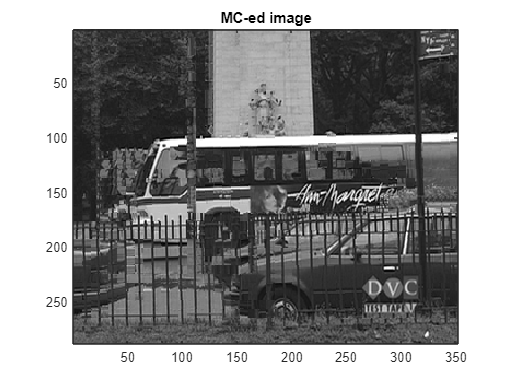

figure(5); image(uint8(compensated));
colormap(gray(256)); axis image; title('MC-ed image');

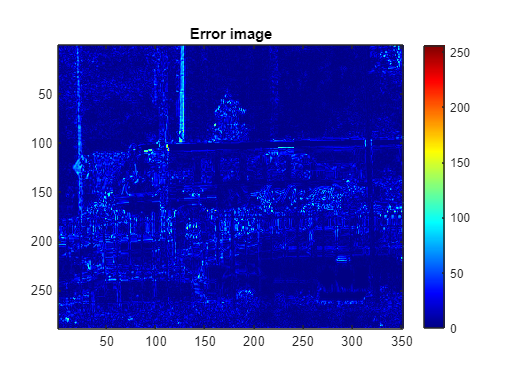

figure(6); imagesc(uint8(abs(error)));
colormap(jet(256)); axis image; title('MC Error image'); colorbar

Show the non-compensated error

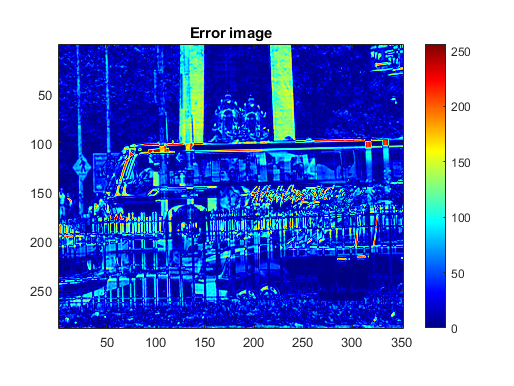

figure(7); image(uint8(abs(current-reference)));
colormap(jet(256)); axis image; title('Error image'); colorbar